# 一元回归模型

% 输入x的样本值
x = [143 145 146 147 149 150 153 154 155 156 157 158 159 160 162 164]';
% 插入\beta0对应列
X = [ones(16, 1) x];
% 输入Y的样本值
Y = [88 85 88 91 92 93 93 95 96 98 97 96 98 99 100 102]';

% 回归分析及检验
[b, bint, r, rint, stats] = regress(Y, X);
b,bint,stats

b =   -16.0730
    0.7194


bint =   -33.7071    1.5612
    0.6047    0.8340


stats =     0.9282  180.9531    0.0000    1.7437


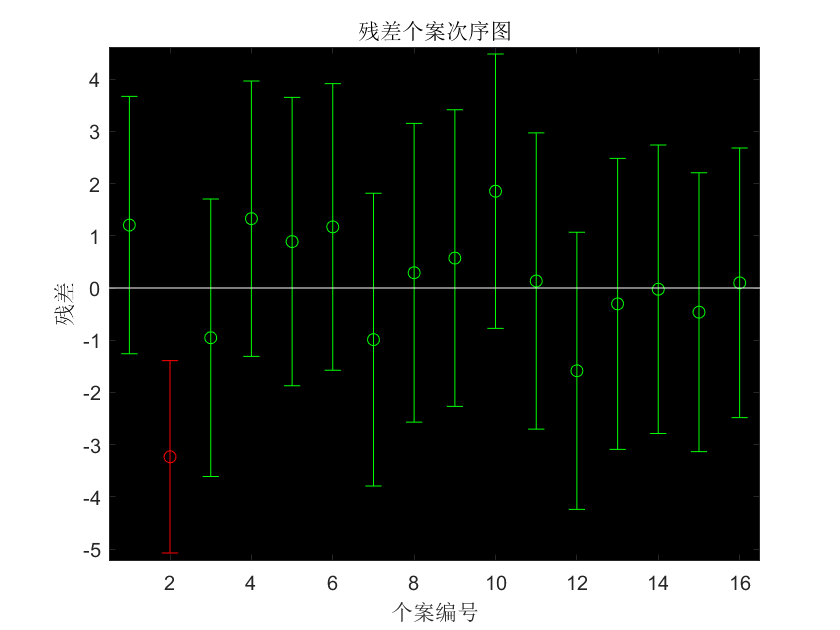

% 残差分析，做残差图
rcoplot(r, rint)

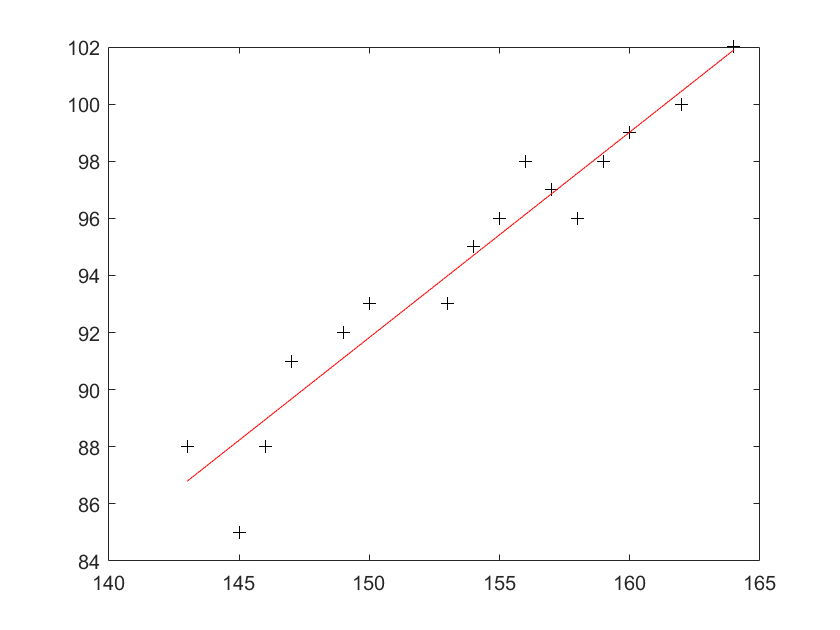


% 预测及作图
z = b(1)+b(2)*x;
plot(x,Y,'k+',x,z,'r')